## 数据去趋势

• `detrend`函数可从您的数据中减去均值或一条最佳拟合线（在最小二乘意义上）。

• 考虑一个表示股票每日价格变动的示例

rng(20)
t = 0:300;
dailyFluct = randn(size(t));
sdata = cumsum(dailyFluct) + 20 + t/100;
mean(sdata)

ans = 41.5155

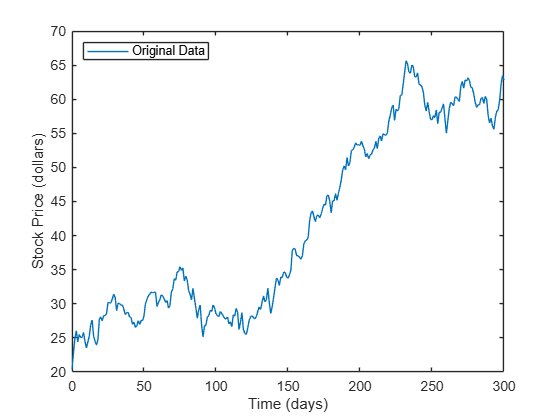

figure
plot(t,sdata);
legend('Original Data','Location','northwest');
xlabel('Time (days)');
ylabel('Stock Price (dollars)');

从数据中移除线性趋势

rng(20)
t = 0:300;
dailyFluct = randn(size(t));
sdata = cumsum(dailyFluct) + 20 + t/100;
mean(sdata)

ans = 41.5155

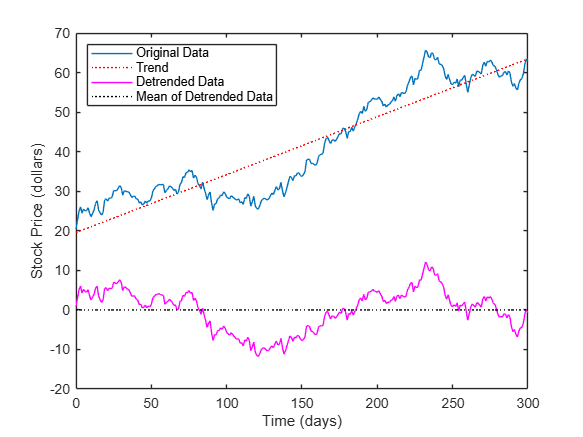

figure
plot(t,sdata);
legend('Original Data','Location','northwest');
xlabel('Time (days)');
ylabel('Stock Price (dollars)');
detrend_sdata = detrend(sdata);
trend = sdata - detrend_sdata;
hold on
plot(t,trend,':r')
plot(t,detrend_sdata,'m')
plot(t,zeros(size(t)),':k')
legend('Original Data','Trend','Detrended Data','Mean of Detrended Data','Location','northwest')
xlabel('Time (days)');
ylabel('Stock Price (dollars)')